% State and state derivatives
syms X_dot u_dot Y_dot v_dot psi_dot r_dot X u Y v psi r 
% Inputs
syms delta_f F_x

%constants
Nw=2;
f=0.01;
Iz=2667;
a=1.35;
b=1.45;
By=0.27;
Cy=1.2;
Dy=0.7;
Ey=-1.6;
Shy=0;
Svy=0;
m=1400;
g=9.806;


%slip angle functions in degrees
a_f=rad2deg(delta_f-atan2(v+a*r,u));
a_r=rad2deg(-atan2((v-b*r),u));

%Nonlinear Tire Dynamics
phi_yf=(1-Ey)*(a_f+Shy)+(Ey/By)*atan(By*(a_f+Shy));
phi_yr=(1-Ey)*(a_r+Shy)+(Ey/By)*atan(By*(a_r+Shy));

F_zf=b/(a+b)*m*g;
F_yf=F_zf*Dy*sin(Cy*atan(By*phi_yf))+Svy;

F_zr=a/(a+b)*m*g;
F_yr=F_zr*Dy*sin(Cy*atan(By*phi_yr))+Svy;

F_total=sqrt((Nw*F_x)^2+(F_yr^2));
F_max=0.7*m*g;
% 
% if F_total>F_max
% 
%     F_x=F_max/F_total*F_x;
% 
%     F_yr=F_max/F_total*F_yr;
% end

%vehicle dynamics
dzdt= [u*cos(psi)-v*sin(psi);...
          (-f*m*g+Nw*F_x-F_yf*sin(delta_f))/m+v*r;...
          u*sin(psi)+v*cos(psi);...
          (F_yf*cos(delta_f)+F_yr)/m-u*r;...
          r;...
          (F_yf*a*cos(delta_f)-F_yr*b)/Iz];

J_z = jacobian(dzdt,[X u Y v psi r]);
J_u = jacobian(dzdt,[delta_f F_x]);

%Operating points
X = 0;
u = 17.88; %17.88 m/s = 40 mph
Y = 0;
v = 10;
psi = 0;
r = 0;
delta_f = 10;
F_x = 50;

A = double(subs(J_z));
B = double(subs(J_u));
subs(dzdt);
% dz_zt_lin = A*(z-z_op) + B*(u-u_op) + subs(dzdt)
[eigvec, lambda] = eig(A);
disp(real(lambda))

         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0    0.3041         0         0
         0         0         0         0   -0.2936         0
         0         0         0         0         0   -0.0000



C = eye(6);
D = zeros(6,2);

t = 0:0.01:10;
Fx = 0*ones(size(t));
deltaf = 0*t;
u = [deltaf; Fx];
dx0 = zeros(1,6);
dx0(2) = 17.88;
system = ss(A,B,C,D)

system =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           1           0           0         -10           0
   x2           0  -4.733e-06           0   8.462e-06           0          10
   x3           0           0           0           1       17.88           0
   x4           0   -0.002781           0    0.004972           0      -17.89
   x5           0           0           0           0           0           1
   x6           0    0.002127           0   -0.003804           0    0.005489
 
  B = 
             u1        u2
   x1         0         0
   x2     2.839  0.001429
   x3         0         0
   x4     1.841         0
   x5         0         0
   x6     1.305         0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1  u2
   

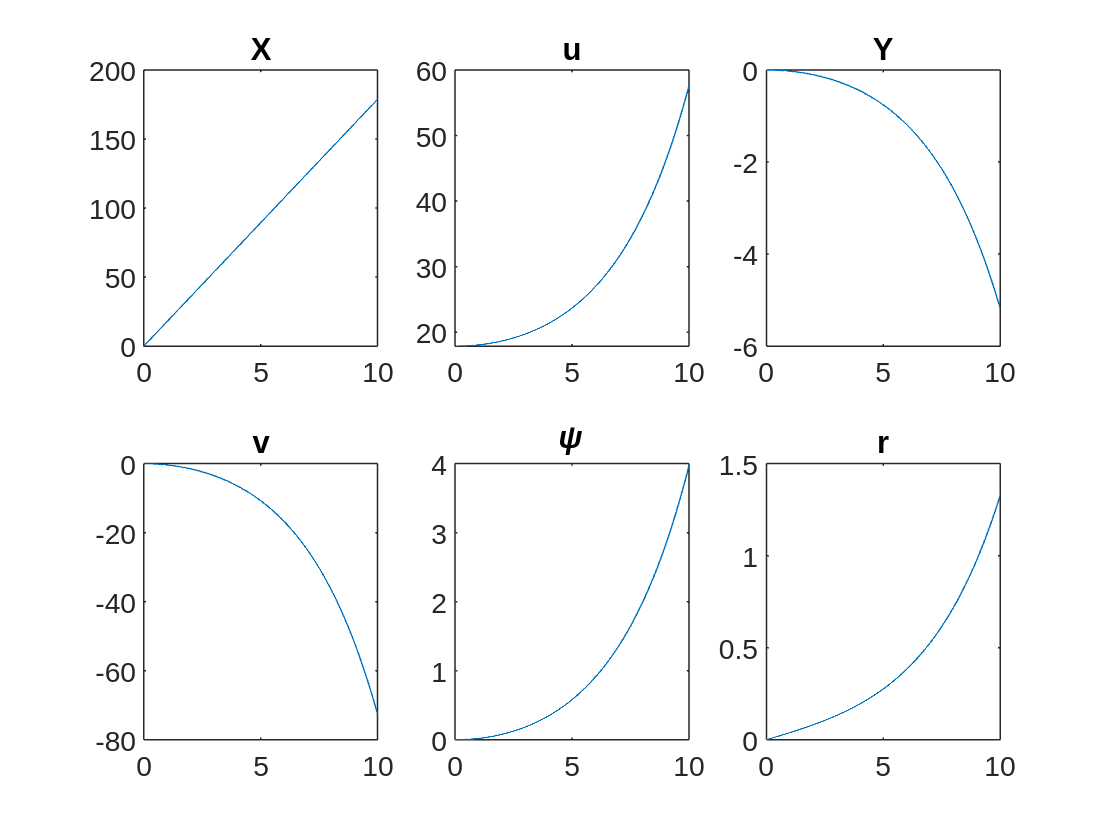

[ylin, t] = lsim(system, u, t, dx0);

labels = ["X", "u", "Y", "v", "\psi", "r"];
figure;
for i = 1:6
    subplot(2,3,i)
    plot(t, ylin(:,i))
    title(labels(i))
end